## ***Pre-Processing &Segmentation Part***

clear all;close all;clc
Fs=44100;

%initiating feature and label matrix which will be used later
features=[];
labels=[];

%fetch audio data
rec=audiorecorder(Fs,16,1);
disp ("Start Recording")

Start Recording


recordblocking(rec,5)
disp("Stop Recording")

Stop Recording


data=getaudiodata(rec); % main data here

%generating file name
type= 0;%type0 for normal& type 1 for parkinson
sub_number = randi(200); % Change 100 to any desired range
filename = ['Typ', num2str(type), '_Sub', num2str(sub_number), '.wav'];
audiowrite(filename, data, Fs);

%this section is for manually loaded data
%recorded by phone or other device
[data,Fs]=audioread("Typ0_Sub1.wav"); %give audio name here
data=data(1:Fs*5);

%making sure data is 1D row vector
if size(data,1)>1 & size(data,2)>=1
   data=data(:,1);%making sure only one channel is getting into data
   data=data';
end

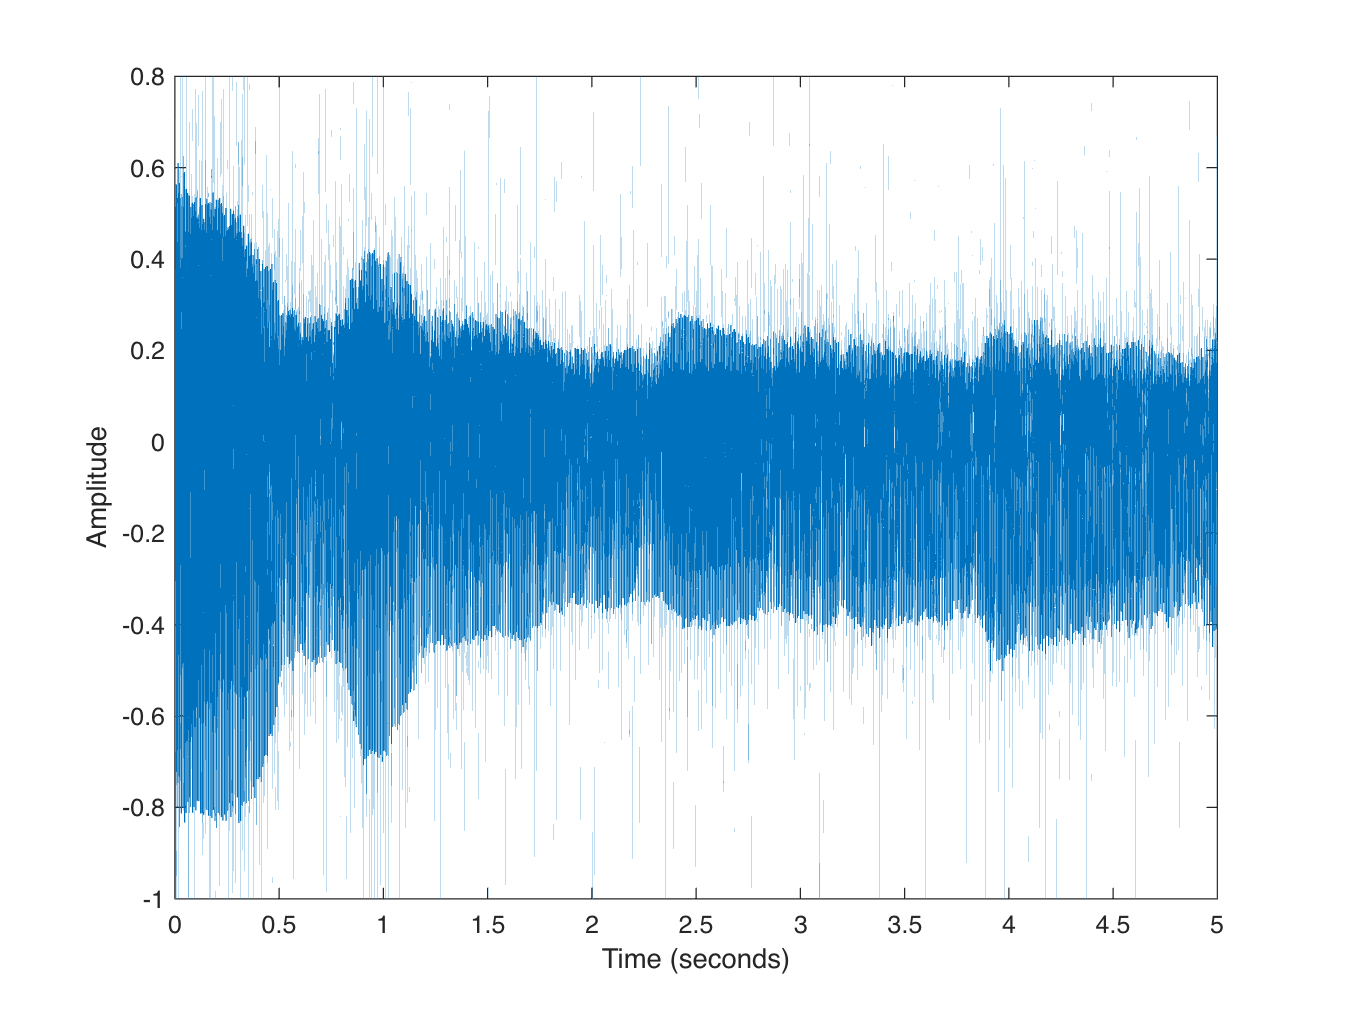

%plotting the input signal
t=(0:length(data)-1)/Fs;
plot(t,data)
xlabel('Time (seconds)')
ylabel('Amplitude')

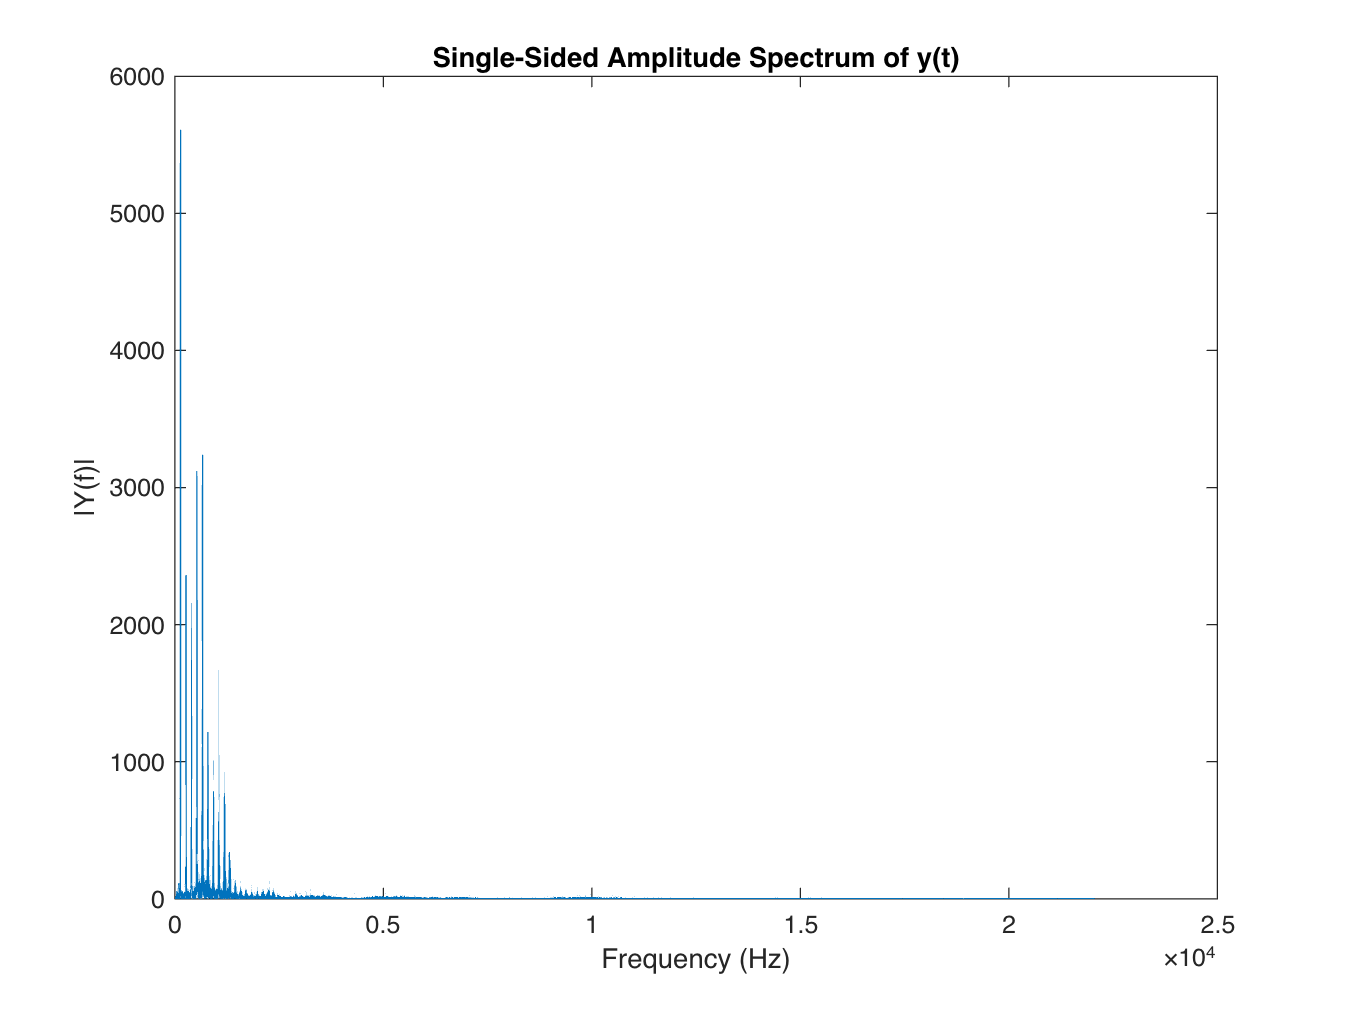

%check fourier Transform of signal
L = length(data);
NFFT = 2^nextpow2(L);
y_fft = abs(fft(data,NFFT));
% creating frequency axis
freq = Fs/2*linspace(0,1,NFFT/2+1);
% Plot single-sided amplitude spectrum.
plot(freq,y_fft(1:NFFT/2+1));
title('Single-Sided Amplitude Spectrum of y(t)');
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');

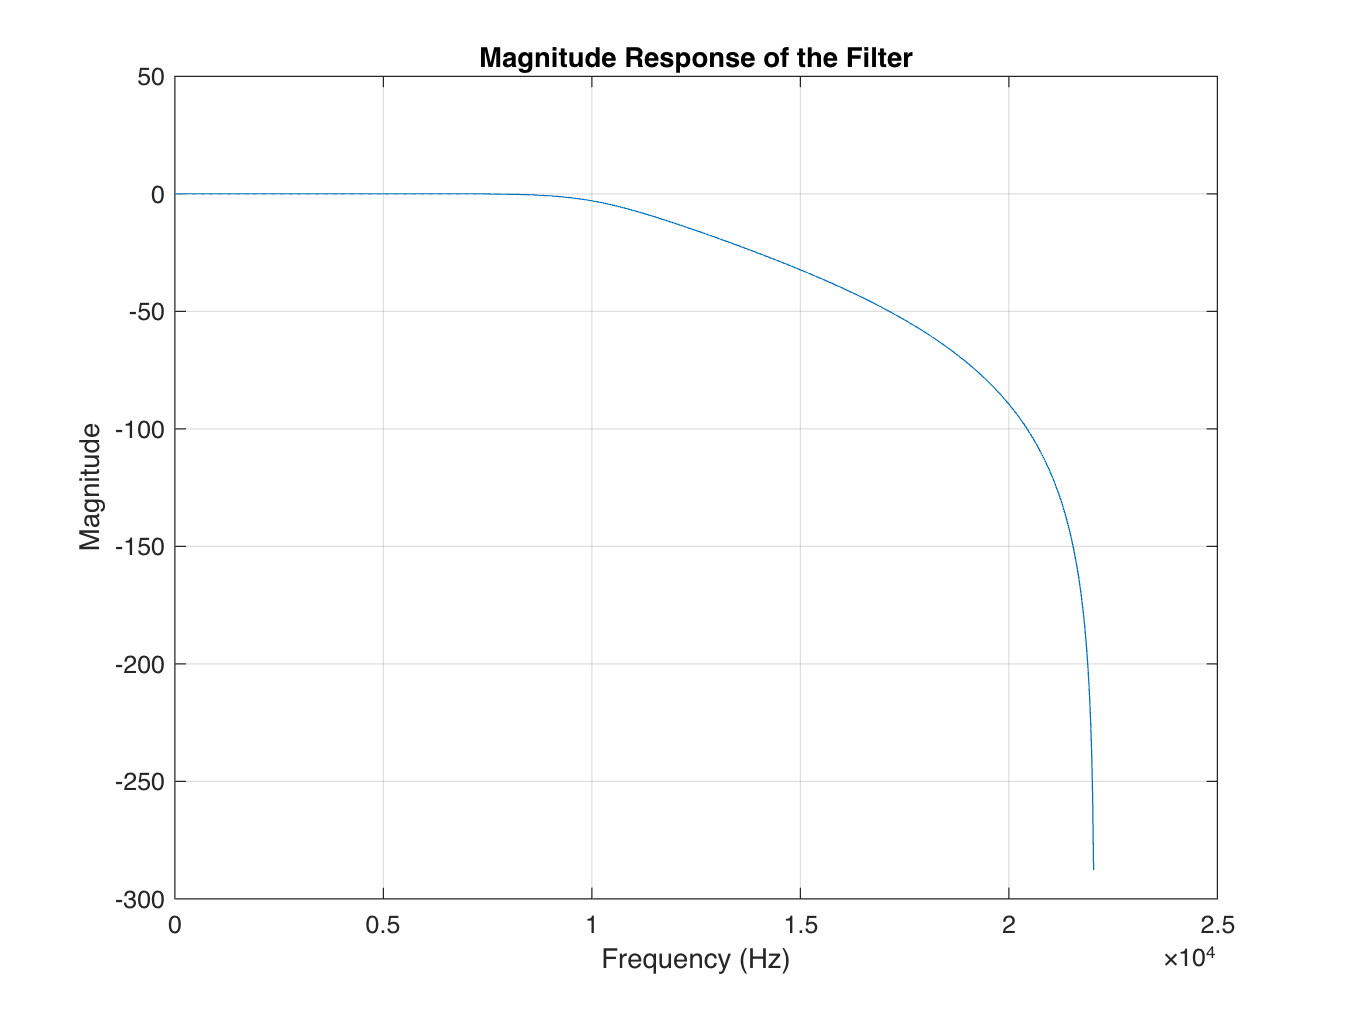

%design filter and do filtering if needed
fc = 10^4; % Cutoff frequency
o = 5; % Order
wn = fc / (Fs/2); % Normalized cutoff frequency
[b,a] = butter(o, wn, 'low');
% See frequency response of the filter
[h,w] = freqz(b, a, 1024, Fs);
plot(w, 20*log10(abs(h)));
title('Magnitude Response of the Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

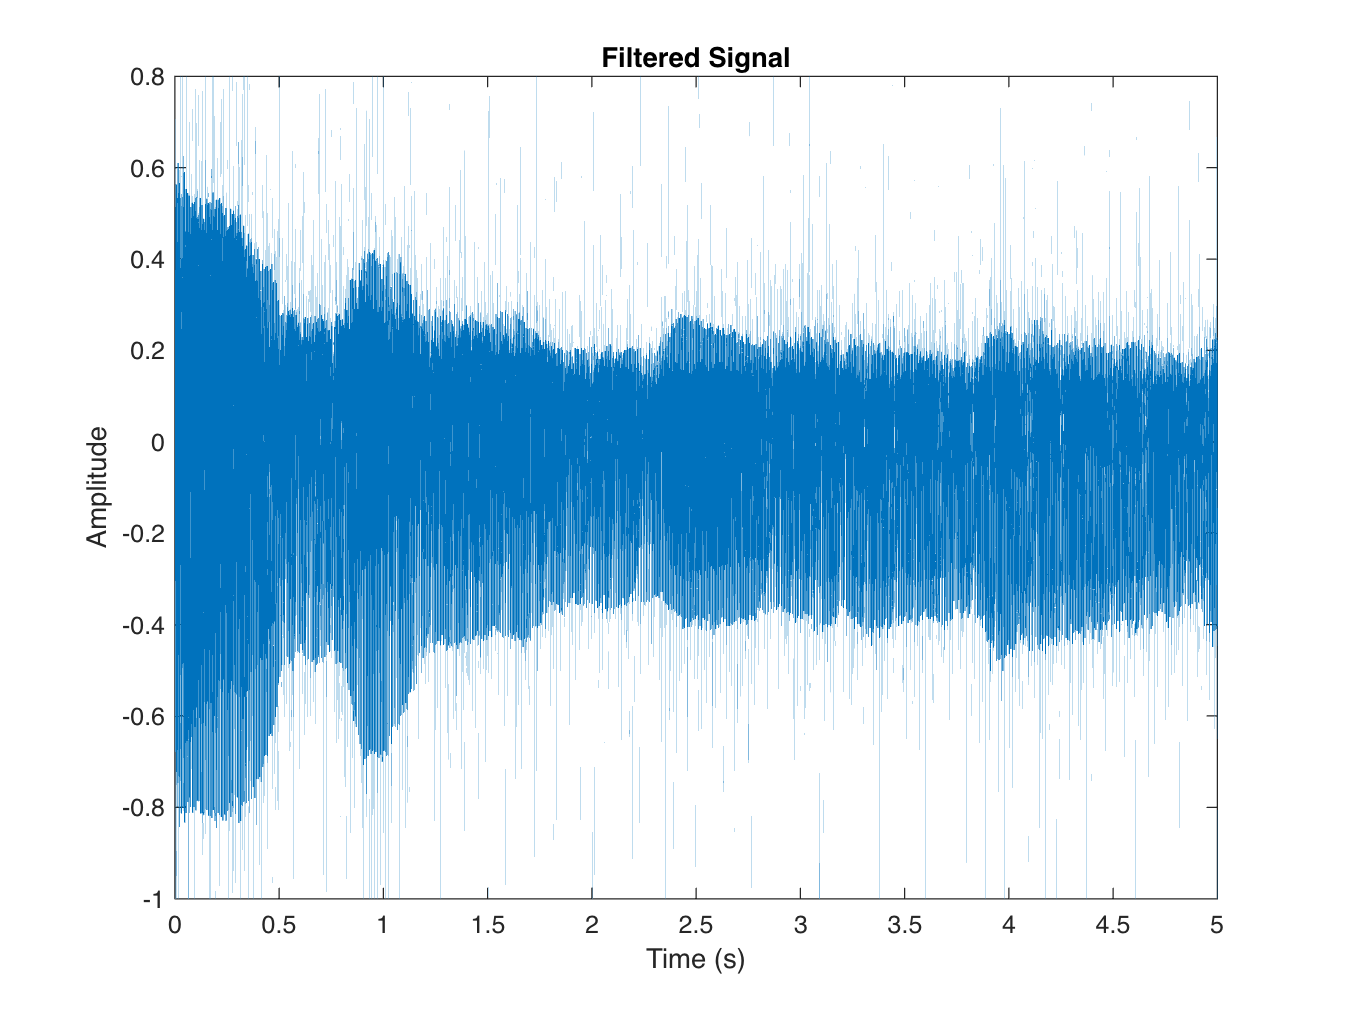

% Filter the signal
data_filtered= filter(b,a,data);
plot(t,data);
title('Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');

data=data_filtered; %overwriting

%segmenting
%output is in segments variable
%hamming also done in same step. Comment out if seems unnecessary
%also each segment is normalized

segment_duration=2.5; %seconds
len_segment = fix((Fs * segment_duration)+1);
num_segments = ceil(length(data) / len_segment);
%ham_win=(hamming(len_segment))';    
% Initializing segments matrix
segments = zeros(num_segments, len_segment);
    
for i = 1:num_segments
   % Determine the start and end indices for the current segment
   start_idx = (i - 1) * len_segment + 1;
   end_idx = min(start_idx + len_segment - 1, length(data));
 
   segment = data(start_idx:end_idx);
        
  if length(segment) < len_segment
      segment = [segment, zeros(1, len_segment - length(segment))]; %zero padding if needed
  end
  
  segment=segment .* ham_win; %comment out if unnecessary
  %max_abs_segment= max(abs(segment));
  %segment=segment/max_abs_segment; %normalizing
  segment = (segment - mean(segment)) / std(segment); %normalizing
  segments(i, :) = segment;
end

%clearing all unncessary variables
clearvars -except segments Fs features labels

## ***Feature Matrix preparing Part***

% arguments(segmented_matrix,person_label,Sampling rate)
[temp_features,temp_labels]=find_features(segments,1,Fs);

%cascading all the features with their labels
features=[features;temp_features];
labels=[labels;temp_labels];

## ***Statistical Analysis Part***

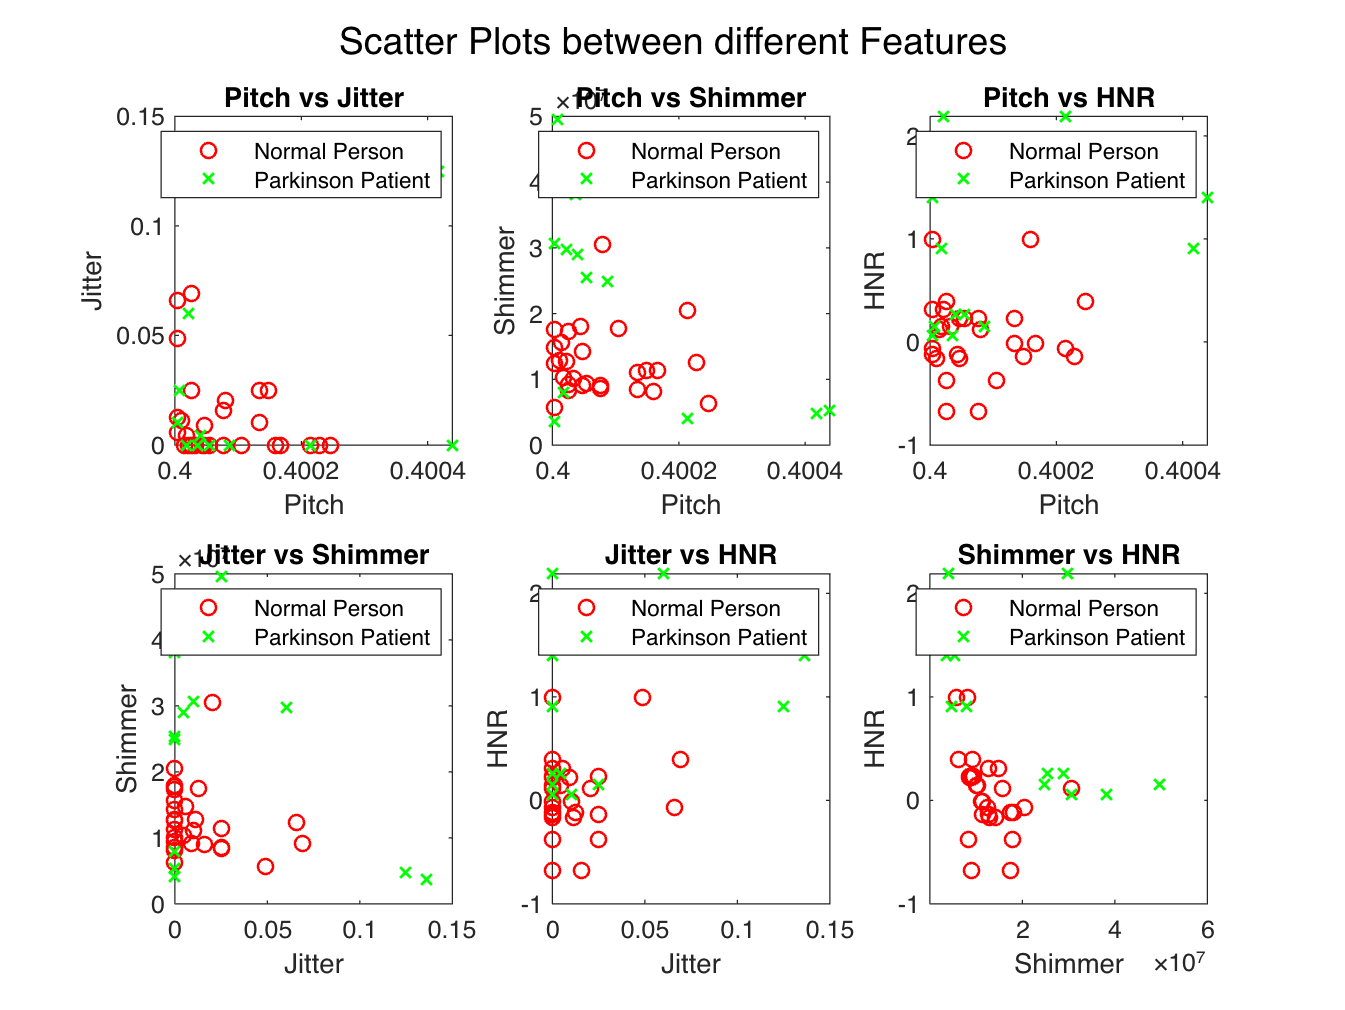

%scatter plot between feature 1 & 2
figure;
subplot(2,3,1)
plot(features(labels==0,1),features(labels==0,2),'ro','LineWidth',1)
hold on
plot(features(labels==1,1),features(labels==1,2),'gx','LineWidth',1)
hold off
xlabel('Pitch')
ylabel('Jitter')
legend('Normal Person','Parkinson Patient')
title('Pitch vs Jitter')

%scatter plot between feature 1 & 3
subplot(2,3,2)
plot(features(labels==0,1),features(labels==0,3),'ro','LineWidth',1)
hold on
plot(features(labels==1,1),features(labels==1,3),'gx','LineWidth',1)
hold off
xlabel('Pitch')
ylabel('Shimmer')
legend('Normal Person','Parkinson Patient')
title('Pitch vs Shimmer')

%scatter plot between feature 1 & 4
subplot(2,3,3)
plot(features(labels==0,1),features(labels==0,4),'ro','LineWidth',1)
hold on
plot(features(labels==1,1),features(labels==1,4),'gx','LineWidth',1)
hold off
xlabel('Pitch')
ylabel('HNR')
legend('Normal Person','Parkinson Patient')
title('Pitch vs HNR')

%scatter plot between feature 2 & 3
subplot(2,3,4)
plot(features(labels==0,2),features(labels==0,3),'ro','LineWidth',1)
hold on
plot(features(labels==1,2),features(labels==1,3),'gx','LineWidth',1)
hold off
xlabel('Jitter')
ylabel('Shimmer')
legend('Normal Person','Parkinson Patient')
title('Jitter vs Shimmer')

%scatter plot between feature 2 & 4
subplot(2,3,5)
plot(features(labels==0,2),features(labels==0,4),'ro','LineWidth',1)
hold on
plot(features(labels==1,2),features(labels==1,4),'gx','LineWidth',1)
hold off
xlabel('Jitter')
ylabel('HNR')
legend('Normal Person','Parkinson Patient')
title('Jitter vs HNR')

%scatter plot between feature 3 & 4
subplot(2,3,6)
plot(features(labels==0,3),features(labels==0,4),'ro','LineWidth',1)
hold on
plot(features(labels==1,3),features(labels==1,4),'gx','LineWidth',1)
hold off
xlabel('Shimmer')
ylabel('HNR')
legend('Normal Person','Parkinson Patient')
title('Shimmer vs HNR')
sgtitle("Scatter Plots between different Features")

% PCA Analysis
[eigvect,D_PCA,eigvals,~,~,mu]=pca(features);

%percentage of variation among different dimensions
percen_variation=(100*eigvals)./sum(eigvals)

percen_variation =   99.999999999999616
   0.000000000000391
   0.000000000000001
   0.000000000000000


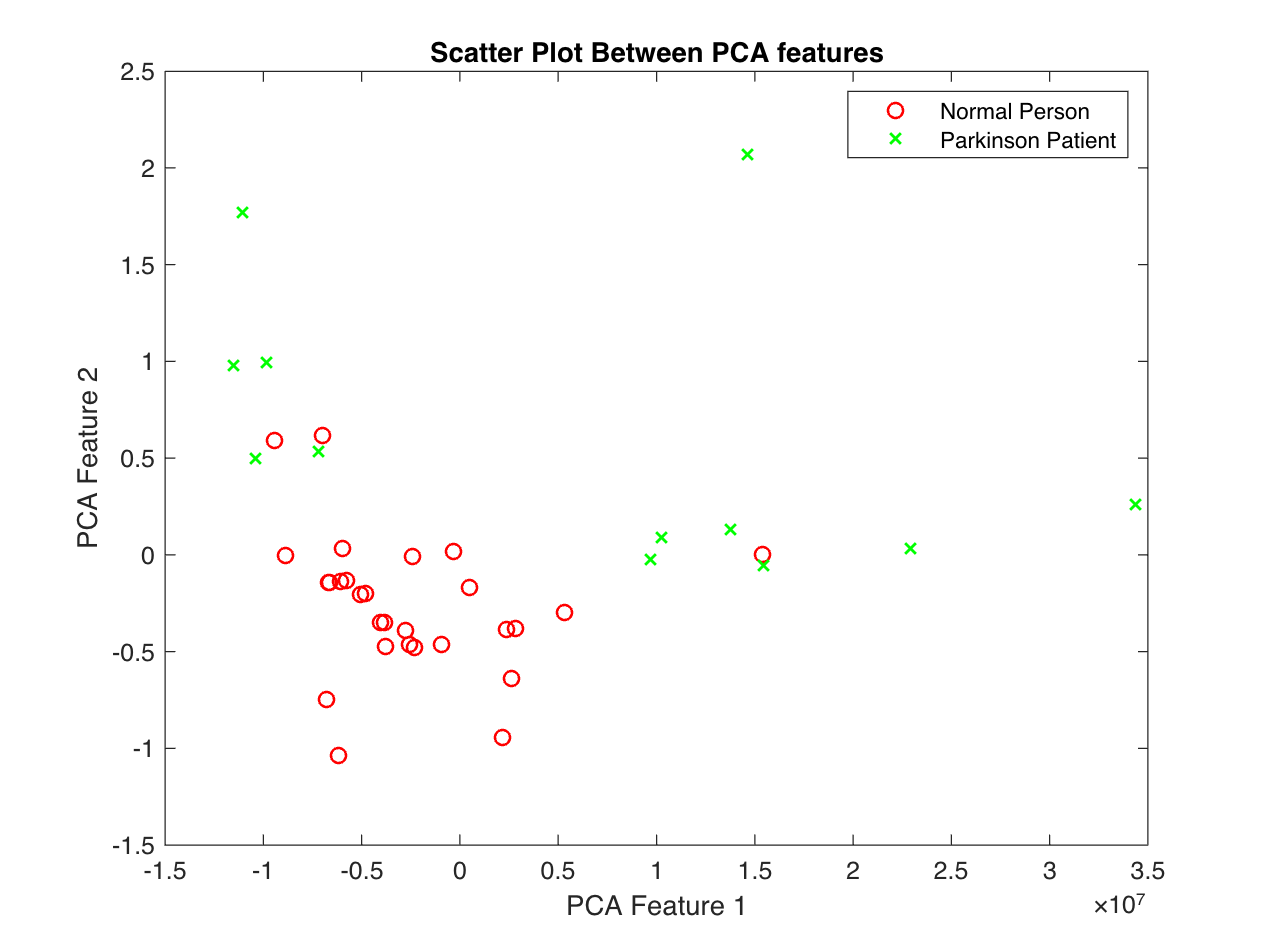

figure;
plot(D_PCA(labels==0,1),D_PCA(labels==0,2),'ro','LineWidth',1)
hold on
plot(D_PCA(labels==1,1),D_PCA(labels==1,2),'gx','LineWidth',1)
hold off
xlabel('PCA Feature 1');
ylabel('PCA Feature 2');
legend('Normal Person','Parkinson Patient')
title('Scatter Plot Between PCA features')

## ***Binary Classification Part***

%creating model 
mdl=fitcsvm(features,labels,'KernelFunction','rbf','KernelScale',1)

mdl =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 40
                    Alpha: [40×1 double]
                     Bias: -0.567558068138196
         KernelParameters: [1×1 struct]
           BoxConstraints: [40×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [40×1 logical]
                   Solver: 'SMO'


  Properties, Methods


%checking accuracy on training set
pdct=predict(mdl,features);
sum(pdct==labels)/length(labels)*100

ans =    100


%Making model from PCA features
mdl_pca=fitcsvm(D_PCA(:,1:2),labels,'KernelFunction','rbf','KernelScale',1)

mdl_pca =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 40
                    Alpha: [40×1 double]
                     Bias: -0.571428571428571
         KernelParameters: [1×1 struct]
           BoxConstraints: [40×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [40×1 logical]
                   Solver: 'SMO'


  Properties, Methods


%checking accuracy of PCA model feature
pdct_pca=predict(mdl_pca,D_PCA(:,1:2));
sum(pdct_pca==labels)/length(labels)*100

ans =    100


### ***FEATURE Matrix COMPUTATION  Function***

function [feat_matrix,label_matrix]=find_features(segments,label,Fs)

**1) Pitch**

[r,c] = size(segments);
pitch = zeros(r,1);
for i = 1:r
    % Compute the autocorrelation function
    temp = segments(i,:);
    autocorr_func = xcorr(temp);
% Find the peaks in the autocorrelation function
   [peaks, peak_locs] = findpeaks(autocorr_func);
% Find the peak with the highest amplitude (excluding the first peak, which corresponds to zero lag)
   [max_peak, max_peak_idx] = max(peaks(2:end));
% Compute the lag corresponding to the peak
   lag = peak_locs(max_peak_idx + 1) - peak_locs(1); % Add 1 to account for excluding the first peak
% Compute the fundamental frequency (F0) in Hz
   F0 = Fs / lag;
   pitch(i) = F0;
end

**2) Jitter**

format long
Tn = 1./pitch;
jitt = zeros(r,1);
for i = 1:r-1
    temp = (1/r-1)*(Tn(i) - Tn(i+1))*100; %expressed as a percentage
    jitt(i+1) = temp;
end
jitt = abs(jitt);

**3) Shimmer**

shim = zeros(r,1);
temp = 0;
temp_shim = zeros(r,1);
for i = 1:r
    temp = segments(i,:);
    for j = 1:c-1
        temp_shim(j+1) = (temp(j) - temp(j+1))/temp(j);
        temp_shim(j+1) = abs(temp_shim(j+1));
    end
    sump = cumsum(temp_shim);
    sump = sump(end);
    
    shim(i) = (1/c-1)*sump*100;
end
shim = abs(shim);

**4) HNR**

xa = zeros(1,c);
for i = 1:c
    xa(i) = mean(segments(:,i));
end
xa_sqr = xa.^2;
H = r*cumsum(xa_sqr);
H = H(end); % harmonic component
noise_comp = 0;
for i = 1:r
    temp = segments(i,:) - xa;
    temp =  temp.^2;
    temp = cumsum(temp);
    noise_comp = noise_comp + temp(end);
end
N = noise_comp;
HNR = 10 * log10(H/N) + zeros(r,1);
feat_matrix=[pitch,jitt,shim,HNR];
%making the label matrix
%label=1; %0 for normal & 1 for parkinson
label_matrix=label*ones(r,1);
end